# Figure 3a - Data range

The first panel of figure 3 will have one or two subjects illustrating the different spectra we obtain as we vary light level and position across days.  We will show lip and tongue separately because they differ in how much variance in the measurements.

We will combine 405 and 415 because the calibration data suggest that the lights are only 5 nm different with a 5 nm spread.

We may include signal to noise w.r.t. reflectance.  There will also be a panel showing how well we fit a weighted sum of the data from our four subjects onto the deVeld subject.

ieInit;
waves = 500:5:700;
symbols = {'kx-','k*-','k^-','ko-'};

T = oeDatabaseCreate;
% theSubject = 'Z'; theDate = '2024-03-14';
% theSubject = 'B'; theDate = '2024-03-19';
theSubject = 'D'; theDate = '2024-03-19';
% theSubject = 'J'; theDate = '2024-03-12';

## Lip:  Excitation light 405 

Read in the files at all excitation levels

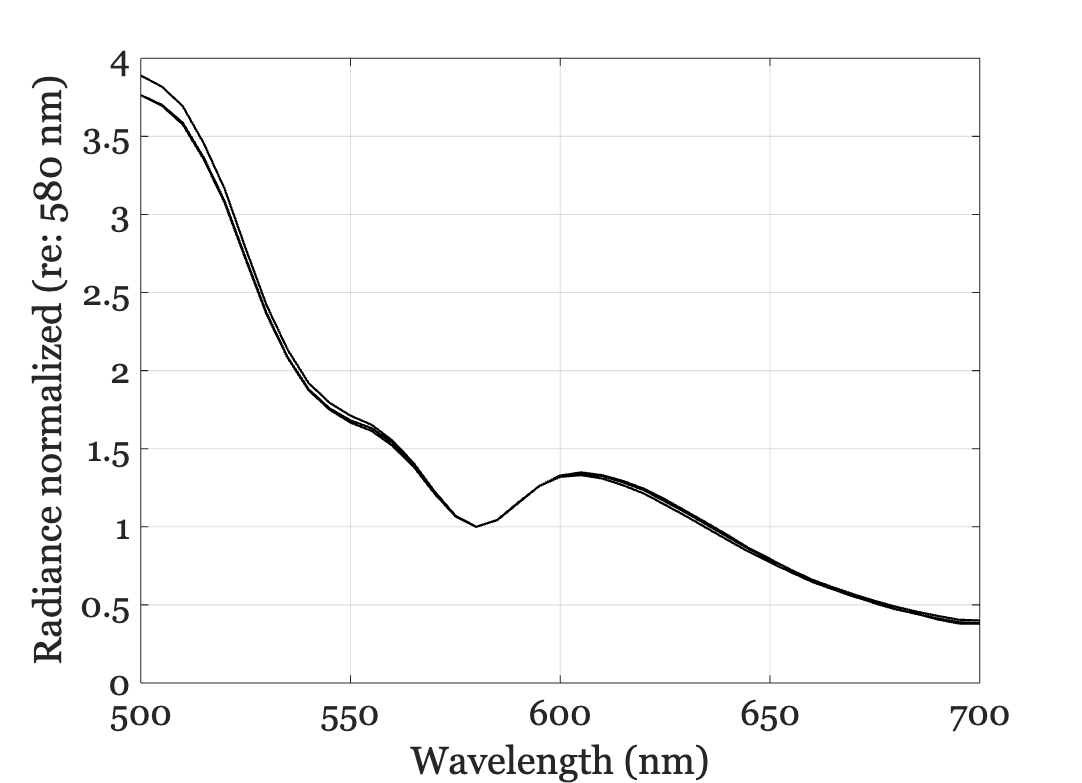

eWave = 405;
[files405,tRows405] = ieTableGet(T,'subject',theSubject,...
    'substrate','lip', ...
    'ewave',eWave, ...
    'date',theDate);

data405 = oeReadFiles(files405,'waves',waves,'normalized wave',580);
ieFigure;
plot(waves,data405,'k-');
xlabel('Wavelength (nm)');
ylabel('Radiance normalized (re: 580 nm)');
grid on;

## Subject 1 (Z) excitation light 415 

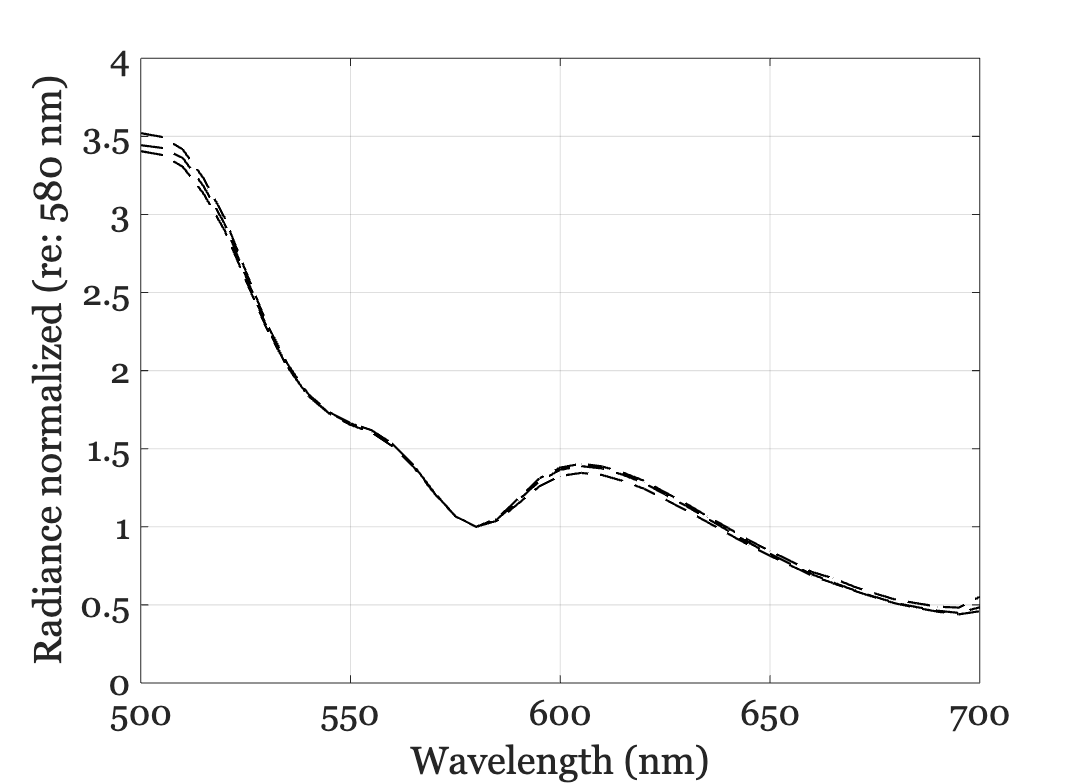

eWave = 415;
files415 = ieTableGet(T,'subject',theSubject,...
    'substrate','lip', ...
    'ewave',eWave, ...
    'date',theDate);

data415 = oeReadFiles(files415,'waves',waves,'normalized wave',580);
ieFigure;
plot(waves,data415,'k--');
xlabel('Wavelength (nm)');
ylabel('Radiance normalized (re: 580 nm)');
grid on;

## Subject 1 (Z) Lip excitation light 450

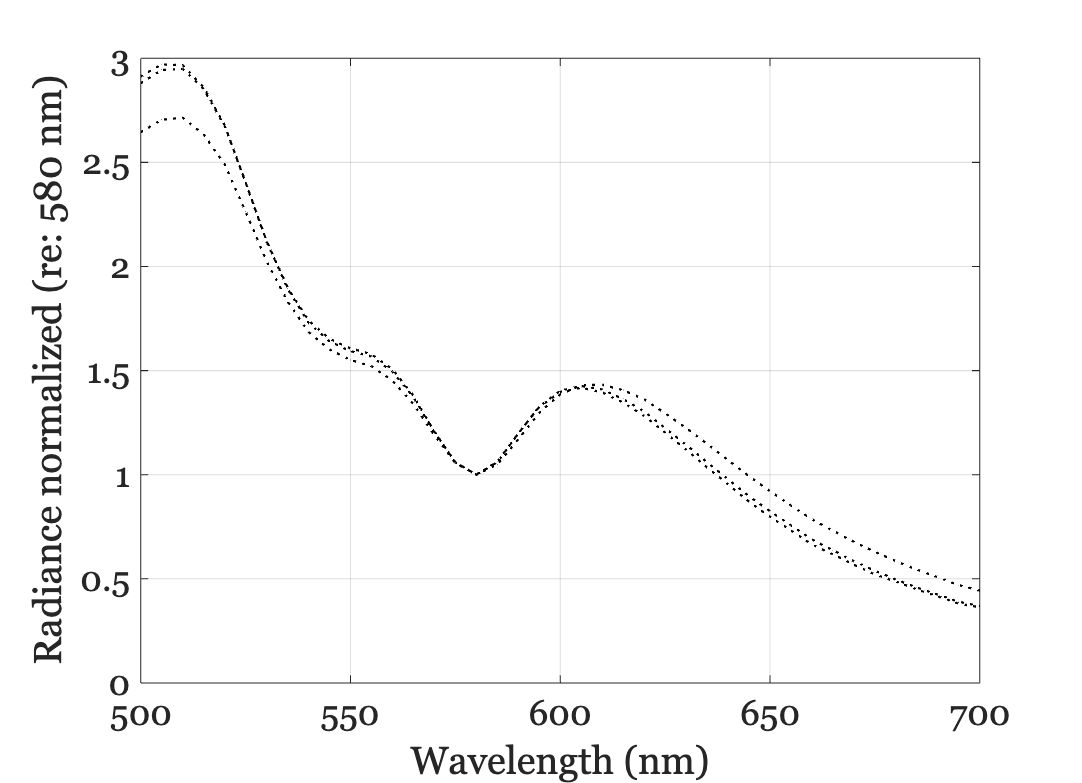

eWave = 450;
files450 = ieTableGet(T,'subject',theSubject,...
    'substrate','lip', ...
    'ewave',eWave, ...
    'date',theDate);

data450 = oeReadFiles(files450,'waves',waves,'normalized wave',580);

ieFigure;
plot(waves,data450,'k:');
xlabel('Wavelength (nm)');
ylabel('Radiance normalized (re: 580 nm)');
grid on;

## Pooled lip 

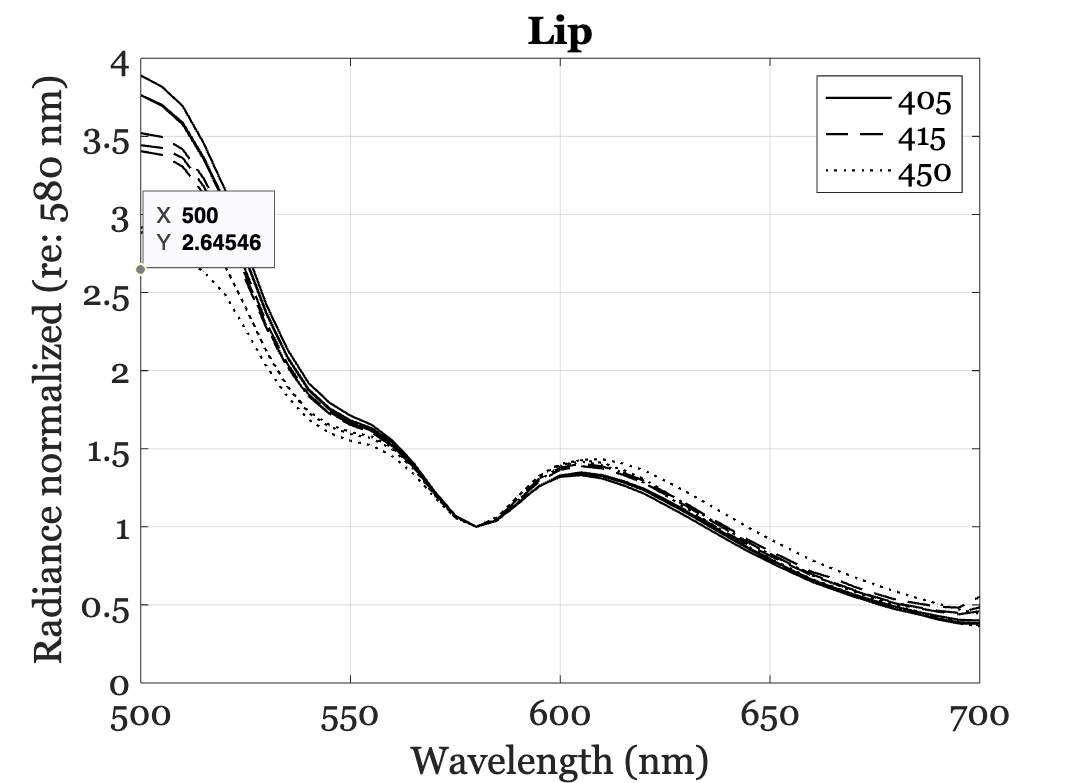

ieFigure;

for ii=1:size(data405,2)
    hA = plot(waves,data405(:,ii),'k-'); hold on;
end
for ii = 1:size(data415,2)
    hB = plot(waves,data415(:,ii),'k--');
end

for ii=1:size(data450,2)
    hC = plot(waves,data450(:,ii),'k:');
end

xlabel('Wavelength (nm)');
ylabel('Radiance normalized (re: 580 nm)');
grid on; title('Lip - all ex')
legend([hA,hB,hC],{'405','415','450'});

## Tongue 405 

Read in the files at all excitation levels

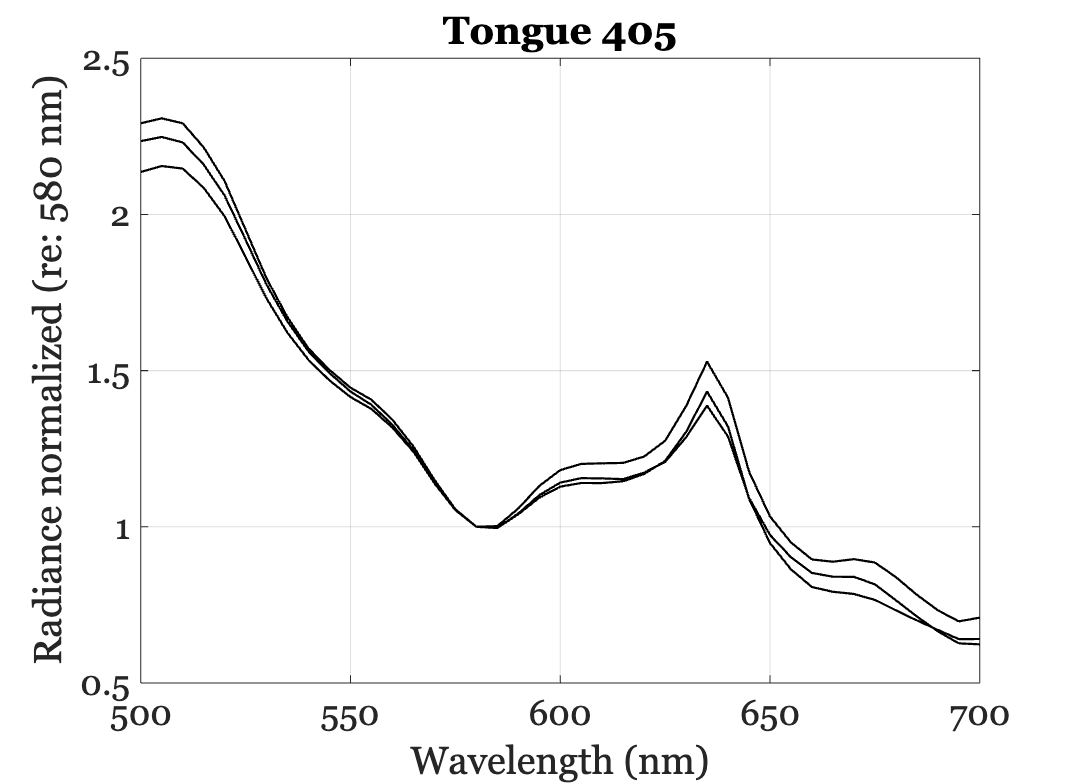

eWave = 405;
files405 = ieTableGet(T,'subject',theSubject,...
    'substrate','tongue', ...
    'ewave',eWave, ...
    'date',theDate);

data405 = oeReadFiles(files405,'waves',waves,'normalized wave',580);

ieFigure;
plot(waves,data405,'k-');
xlabel('Wavelength (nm)');
ylabel('Radiance normalized (re: 580 nm)');
grid on;
title('Tongue 405');

## Tongue 415

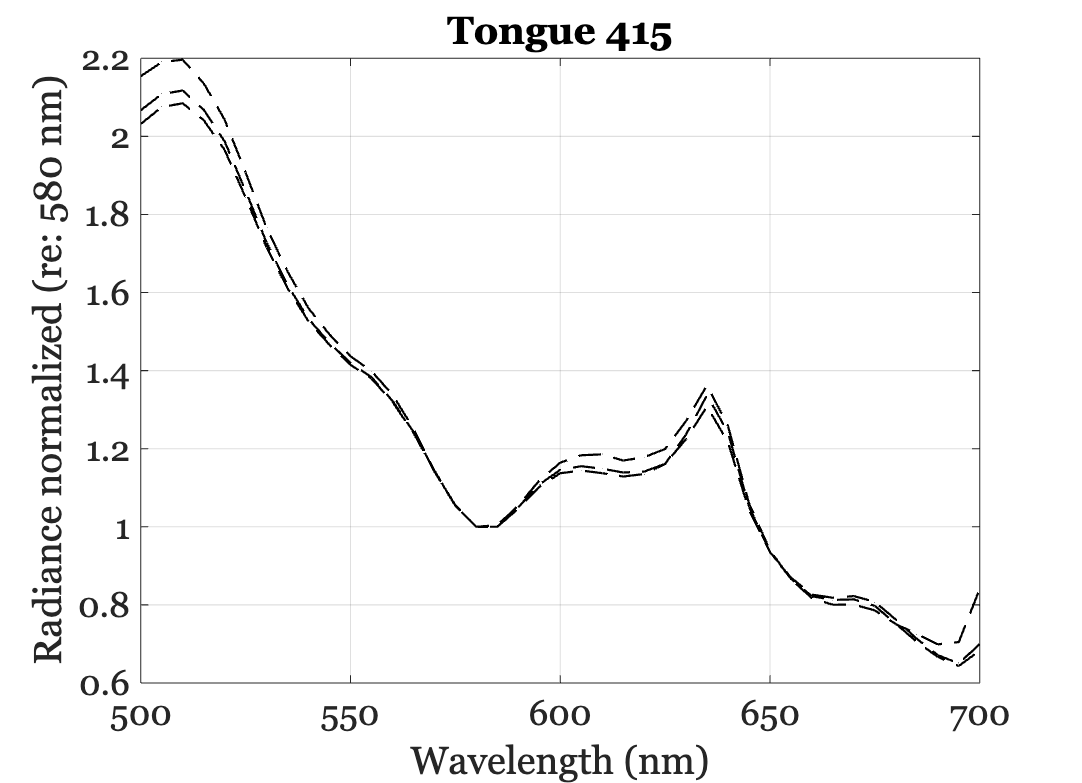

eWave = 415;
files415 = ieTableGet(T,'subject',theSubject,...
    'substrate','tongue', ...
    'ewave',eWave, ...
    'date',theDate);

data415 = oeReadFiles(files415,'waves',waves,'normalized wave',580);
ieFigure;
plot(waves,data415,'k--');
xlabel('Wavelength (nm)');
ylabel('Radiance normalized (re: 580 nm)');
grid on;
title('Tongue 415');

## Tongue  450

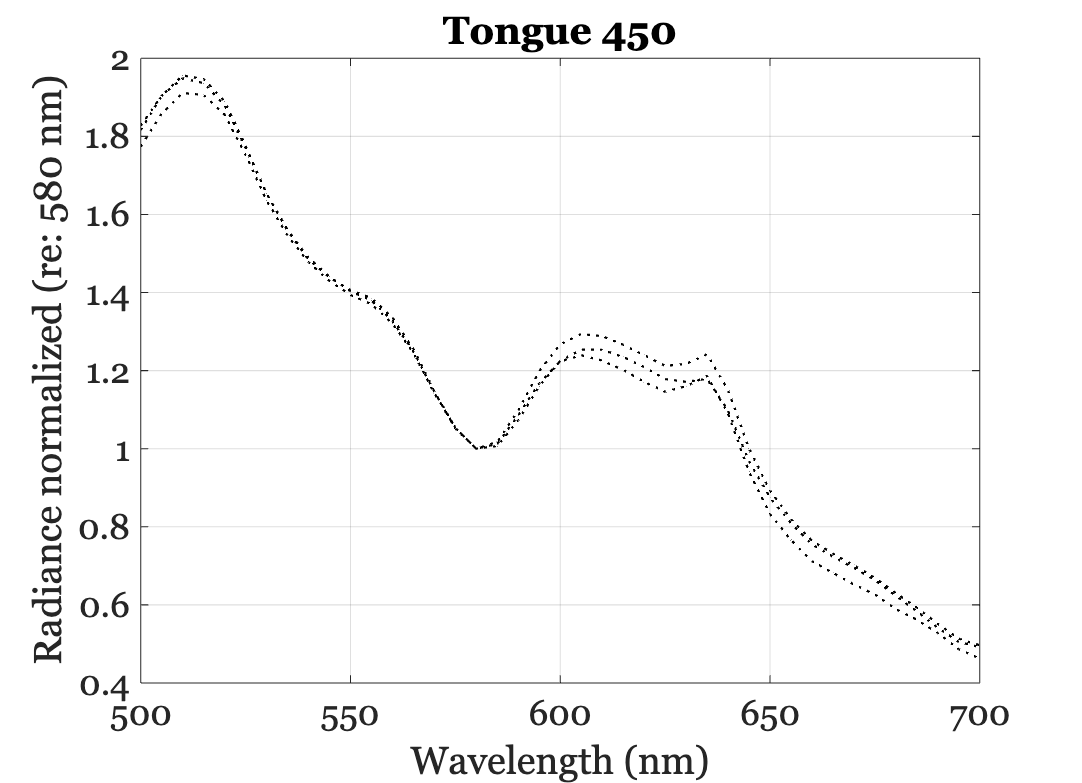

eWave = 450;
files450 = ieTableGet(T,'subject',theSubject,...
    'substrate','tongue', ...
    'ewave',eWave, ...
    'date',theDate);

data450 = oeReadFiles(files450,'waves',waves,'normalized wave',580);

ieFigure;
plot(waves,data450,'k:');
xlabel('Wavelength (nm)');
ylabel('Radiance normalized (re: 580 nm)');
grid on;
title('Tongue 450');

## Pooled tongue

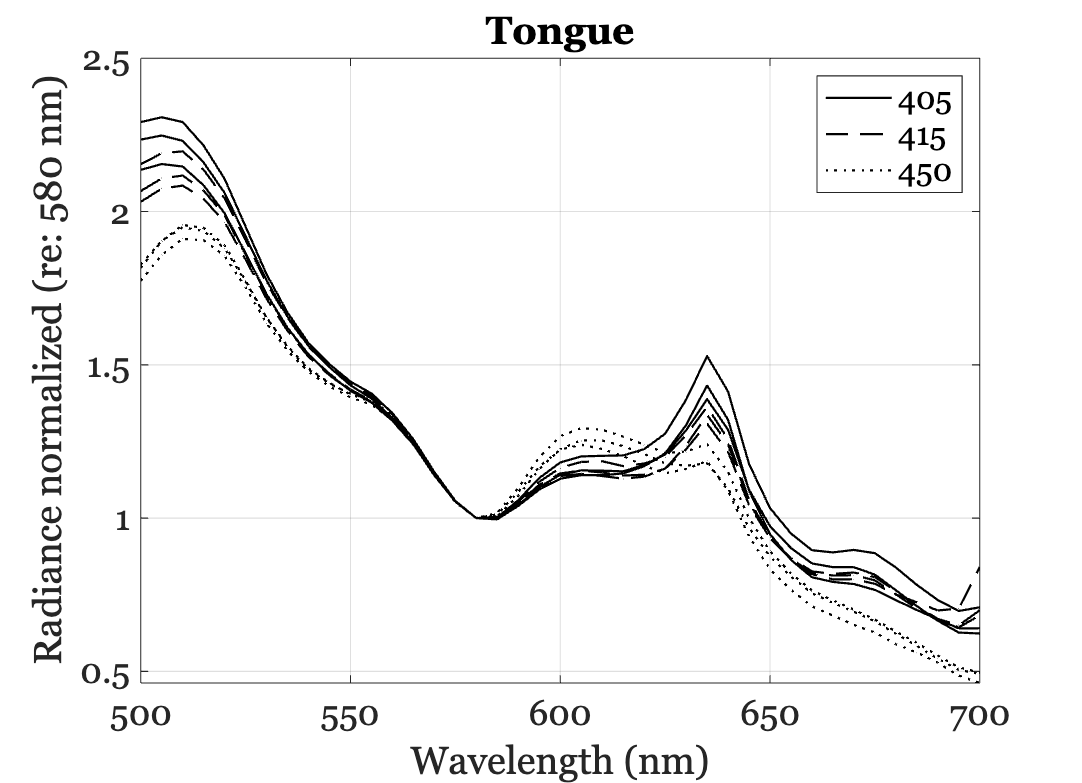

ieFigure;

for ii=1:size(data405,2)
    hA = plot(waves,data405(:,ii),'k-'); hold on;
end
for ii = 1:size(data415,2)
    hB = plot(waves,data415(:,ii),'k--');
end

for ii=1:size(data450,2)
    hC = plot(waves,data450(:,ii),'k:');
end

xlabel('Wavelength (nm)');
ylabel('Radiance normalized (re: 580 nm)');
grid on; title('Tongue all ex')
legend([hA,hB,hC],{'405','415','450'});